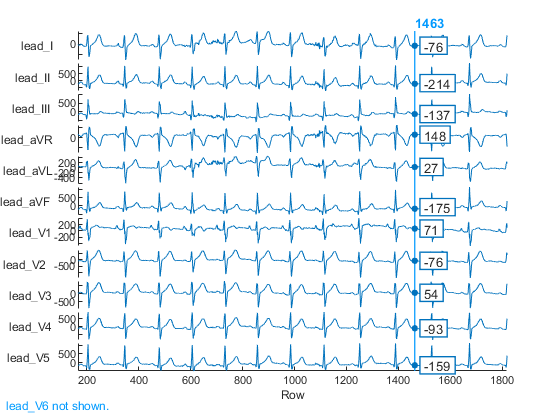

ans = 2000×12 table
    lead_I    lead_II    lead_III    lead_aVR    lead_aVL    lead_aVF    lead_V1    lead_V2    lead_V3    lead_V4    lead_V5    lead_V6
    ______    _______    ________    ________    ________    ________    _______    _______    _______    _______    _______    _______

     -38       -186        -148        109          54         -164        71         -38        87         -54       -137        -60  
     -27       -181        -153        104          60         -164        71         -32        93         -43       -137        -60  
     -27       -181        

% acquire12LeadECG("C:\Users\Nihal\Desktop\0000003_20210307185021_ECGData.txt")
% acquire12LeadECG("C:\Users\Nihal\Desktop\ECGData.txt")
filename= "C:\Users\Nihal\Desktop\ECGData.txt"
hotlerECG(filename,"headerLine",6,"plot","Yes","signalLength",2000)

% function ecg12Leads=acquire12LeadECG(filename, option)
% arguments
%     filename
%     option.signalLength (1,:) {mustBeNumeric,mustBeNonnegative} = 1000
%     option.plot {mustBeMember(option.plot,["Yes","No"])} = "Yes"
%     option.headerLine (1,1) int8 = 6
% end
% 
% % filename="C:\Users\Nihal\Desktop\0000003_20210307185021_ECGData.txt";
% 
% fileID = fopen(filename);
% C = textscan(fileID,'%d64 %d64 %d64 %d64 %d64 %d64 %d64 %d64 %d64 %d64 %d64 %d64',"HeaderLines",option.headerLine);
% fclose(fileID);
% % whos C
% 
% % if signalLength
% % signalLength= option.signalLength;
% 
% if option.signalLength == 1000
%     signalLength=option.signalLength;
% else
%     signalLength = length(C{1,1});
% end
%     
%     lead_I = C{1,1}(1:signalLength);
%     lead_II = C{1,2}(1:signalLength);
%     lead_III = C{1,3}(1:signalLength);
%     lead_aVR = C{1,4}(1:signalLength);
%     lead_aVL = C{1,5}(1:signalLength);
%     lead_aVF = C{1,6}(1:signalLength);
%     lead_V1 = C{1,7}(1:signalLength);
%     lead_V2 = C{1,8}(1:signalLength);
%     lead_V3 = C{1,9}(1:signalLength);
%     lead_V4 = C{1,10}(1:signalLength);
%     lead_V5 = C{1,11}(1:signalLength);
%     lead_V6 = C{1,12}(1:signalLength);
%     
%     
%     ecg12Leads=table(lead_I,lead_II,lead_III,lead_aVR,lead_aVL,lead_aVF,lead_V1,lead_V2,lead_V3,lead_V4,lead_V5,lead_V6);
%     if option.plot == "Yes"
%         stackedplot(ecg12Leads);
%     end
% end
% 